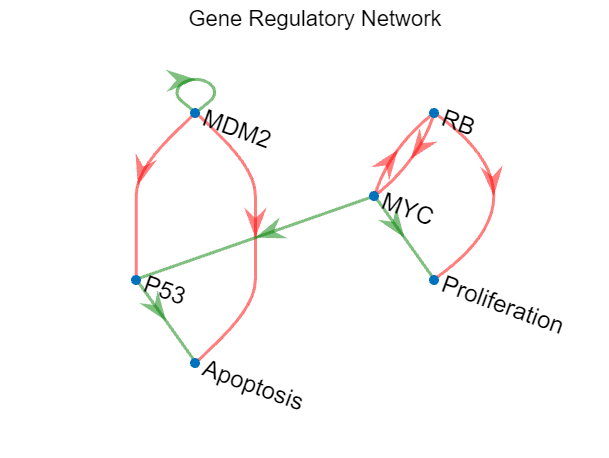

%% Initialize
clear; clc;
addpath('.');
% C:\Users\shiva\OneDrive\Documents\MATLAB\CompSysBio
%% Part A: Show regulatory diagram
plot_regulatory_diagram();


%% Part B: Truth table analysis
fprintf('\n--- Truth Table Analysis ---\n');


--- Truth Table Analysis ---


fprintf('The states are taken as [P53, MDM2, MYC, RB]\n')

The states are taken as [P53, MDM2, MYC, RB]


states = dec2bin(0:15,4) - '0'; % All possible 4-bit combinations
feasible_states = [];

for i = 1:16
    current_state = states(i,:);
    [new_state, cell_fate] = boolean_update(current_state);
    
    % Check biological feasibility
    if new_state(3) == ~new_state(4)  % MYC and RB must be opposites
        feasible = "Feasible";
        feasible_states = [feasible_states; current_state];
    else
        feasible = "Infeasible";
    end
    
    fprintf('State %2d: %s → %s | Fate: %-4s | %s\n',...
            i-1, num2str(current_state), num2str(new_state),...
            cell_fate, feasible);
end

State  0: 0  0  0  0 → 0  0  1  1 | Fate: None | Infeasible
State  1: 0  0  0  1 → 0  0  0  1 | Fate: None | Feasible
State  2: 0  0  1  0 → 1  0  1  0 | Fate: P    | Feasible
State  3: 0  0  1  1 → 1  0  0  0 | Fate: None | Infeasible
State  4: 0  1  0  0 → 0  1  1  1 | Fate: None | Infeasible
State  5: 0  1  0  1 → 0  1  0  1 | Fate: None | Feasible
State  6: 0  1  1  0 → 0  1  1  0 | Fate: P    | Feasible
State  7: 0  1  1  1 → 0  1  0  0 | Fate: None | Infeasible
State  8: 1  0  0  0 → 0  0  1  1 | Fate: A    | Infeasible
State  9: 1  0  0  1 → 0  0  0  1 | Fate: A    | Feasible
State 10: 1  0  1  0 → 1  0  1  0 | Fate: AP   | Feasible
State 11: 1  0  1  1 → 1  0  0  0 | Fate: A    | Infeasible
State 12: 1  1  0  0 → 0  1  1  1 | Fate: None | Infeasible
State 13: 1  1  0  1 → 0  1  0  1 | Fate: None | Feasible
State 14: 1  1  1  0 → 0  1  1  0 | Fate: P    | Feasible
State 15: 1  1  1  1 → 0  1  0  0 | Fate: None | Infeasible


fprintf('\n')



%% Part C: Attractor analysis
fprintf('\n--- Attractor Analysis ---\n');


--- Attractor Analysis ---


initial_states = [0 0 0 0; 1 1 1 1; 0 1 0 1]; % Example initial conditions

for i = 1:size(initial_states,1)
    state_history = [];
    current_state = initial_states(i,:);
    
    fprintf('\nSimulating initial state: %s\n', num2str(current_state));
    
    while true
        state_history = [state_history; current_state];
        [new_state, ~] = boolean_update(current_state);
        
        if ismember(new_state, state_history, 'rows')
            cycle_start = find(ismember(state_history, new_state, 'rows'),1);
            cycle = state_history(cycle_start:end,:);
            
            if size(cycle,1) == 1
                fprintf('Stable state: %s\n', num2str(new_state));
            else
                fprintf('Oscillation detected between:\n');
                disp(cycle);
            end
            break;
        end
        
        current_state = new_state;
    end
end


Simulating initial state: 0  0  0  0


Oscillation detected between:


     0     0     1     1
     1     0     0     0




Simulating initial state: 1  1  1  1


Oscillation detected between:


     0     1     0     0
     0     1     1     1




Simulating initial state: 0  1  0  1


Stable state: 0  1  0  1




%% Part D: Drug simulations
fprintf('\n--- Drug Simulations ---\n');


--- Drug Simulations ---


drugs = {'A: MDM2 Inhibitor', 'B: MYC Inhibitor', 'C: RB Activator'};
initial_state = [1 1 0 0]; % Example initial state

for d = 1:3
    fprintf('\nTesting %s:\n', drugs{d});
    current_state = initial_state;
    
    for t = 1:3 % Simulate 3 time steps
        [new_state, cell_fate] = boolean_update(current_state);
        
        % Apply drug effects
        switch d
            case 1, new_state(2) = 0; % MDM2 inhibition
            case 2, new_state(3) = 0; % MYC inhibition
            case 3, new_state(4) = 1; % RB activation
        end
        
        fprintf('Time %d: %s → Fate: %s\n',...
                t, num2str(new_state), cell_fate);
        current_state = new_state;
    end
end


Testing A: MDM2 Inhibitor:


Time 1: 0  0  1  1 → Fate: None
Time 2: 1  0  0  0 → Fate: None
Time 3: 0  0  1  1 → Fate: A



Testing B: MYC Inhibitor:


Time 1: 0  1  0  1 → Fate: None
Time 2: 0  1  0  1 → Fate: None
Time 3: 0  1  0  1 → Fate: None



Testing C: RB Activator:


Time 1: 0  1  1  1 → Fate: None
Time 2: 0  1  0  1 → Fate: None
Time 3: 0  1  0  1 → Fate: None
